# Viene creato l'oggetto "probability distribution" tramite  makedist

Ad esempio per creare l'oggetto probability distribution riferito alla distribuzione normale standardizzata

I pametri della normale mu e sigma sono di default 0 e 1

pdINI=makedist('Normal')

pdINI =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


Esempio di chiamata a makedist con parametri specificati

pd=makedist("Normal","mu",1,"sigma",2)

pd =   NormalDistribution

  Normal distribution
       mu = 1
    sigma = 2


## Distribuzione N(1,4)

## Grafico della densità della distribuzione specificata da makedist.

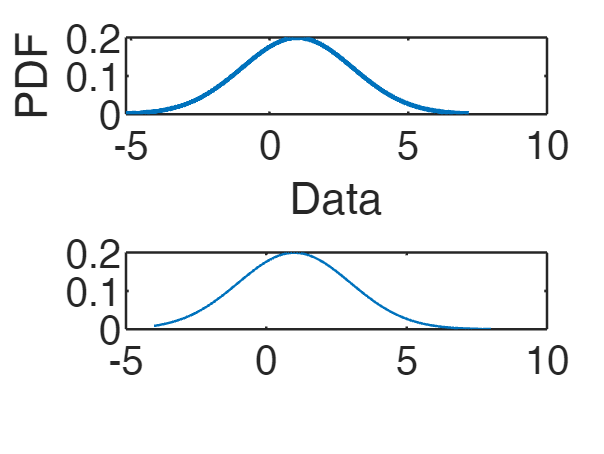

% L'intervallo di valori x è scelto in automatico
subplot(2,1,1)
plot(pd)

subplot(2,1,2)
% L'intervallo di valori x è specificato dall'utente
x = -4:.1:8;
pdf_normal = pdf(pd,x);
plot(x,pdf_normal)

## Distribuzione Weibull (W(1,1))

I parametri di default a e b della Weibull sono di default 1, 1. Nel testo i parametri a e b sono chiamati lambda e k

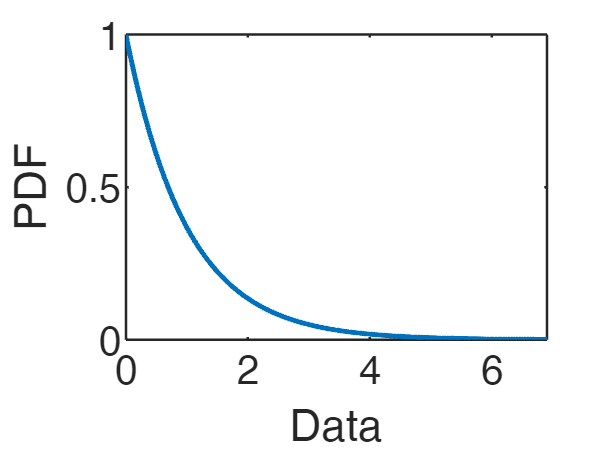

figure
pd=makedist('Weibull');
plot(pd)

## Distribuzione Weibull($\lambda, k$) con parametri con $\lambda$ e  $ k$ specificati dall'utente

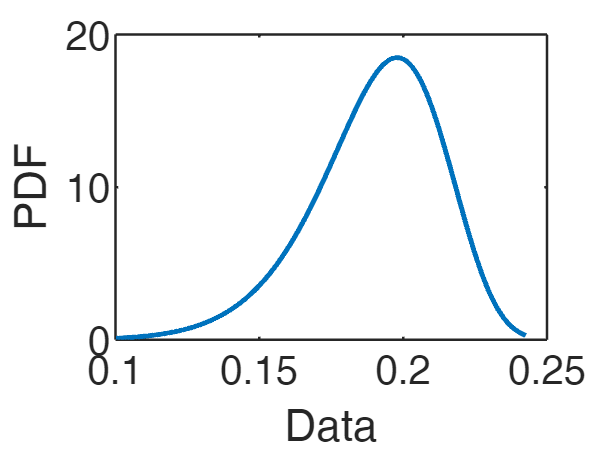

figure
lambda=0.2; % parametro di scala
k=10; % parametro di forma
pd=makedist('Weibull','a',lambda,'b',k);
plot(pd)

## Numeric slider per mostrare l'effetto dei parametri sulla densità Weibull

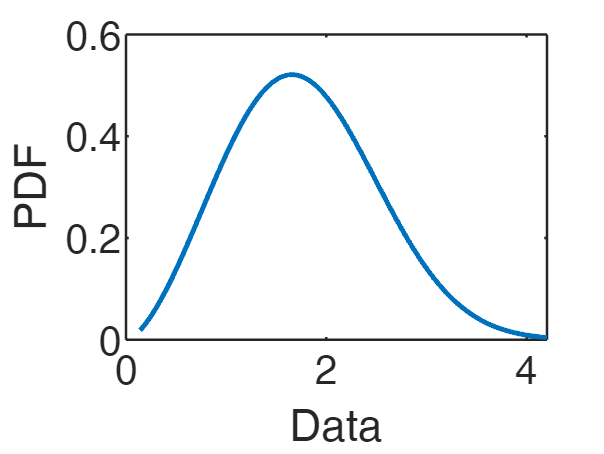

figure
lambda=2; % parametro di scala
k=2.6; % parametro di forms
pd=makedist('Weibull','a',lambda,'b',k);
plot(pd)